clc
clear 
close all
feature('DefaultCharacterSet','UTF8');
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex'); 
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultTextFontsize',13);
set(groot, 'defaultAxesFontsize',13);
set(groot, 'defaultLegendFontsize',13);
set(groot, 'defaultLegendLocation','best');
set(0, 'DefaultLineLineWidth', 1.6);
pt = 12;
myBlue =1/255* [79 145 195];
myGreen = 1/255*[79 195 129];
show = 1;


%modelling structure-main
nbNodes=16;%number of nodes at the ends of the beams.
nbElem=1;%nbr of elements per beam.
%data
E=210*10^9; %[N/m^2], Young modulus
nu=0.3; %[-], poisson ratio
D=100e-3; %[m], diameter
R=50e-3; %[m], radius
A=R^2*pi; %[m^2], section area
G=E/(2*(1+nu)); %[N/m^2], shear modulus
Iy=pi*D^4/64; %[m^4],
Iz=Iy; %[m^4]
Jx=Iy+Iz; %[m^4]
rho=7800; %[kg/m^3], density

%Nodes at each end of each element of the structure.
elemList=zeros(nbNodes,2);
for i=1:nbNodes
    elemList(i,1)=i;
    if i==nbNodes
        elemList(i,2)=1;
    else
        elemList(i,2)=i+1;
    end
end
elemList=[elemList;1 8; 2 8; 2 15; 3 6;3 7; 3 8; 3 14; 4 6; 4 13; 5 12; 6 11; 7 10; 9 14; 9 15; 9 16; 10 14; 11 13; 11 14];
if nbElem~=1
    newElemList=elemList_fun(elemList,nbElem,nbNodes);
end
%list of the coordinates of each node.
nodeList=zeros(nbNodes,3);
nbNodesL1=5; %number of nodes on the horizontal line at y=0, z=0.
for i=1:nbNodesL1
    nodeList(i,2)=0;
    nodeList(i,3)=0;
    if i==1
        nodeList(i,1)=0;
    else
        nodeList(i,1)=nodeList(i-1,1)+12/(nbNodesL1-1);
    end
end
nbNodesL2=3; %number of nodes on the horizontal line at y=0, z=3.
for i=nbNodesL1+1:nbNodesL2+nbNodesL1
    nodeList(i,2)=0;
    nodeList(i,3)=3;
    if i==nbNodesL1+1
        nodeList(i,1)=9;
    else
        nodeList(i,1)=nodeList(i-1,1)-6/(nbNodesL2-1);
    end
end
nbNodesL3=3; %number of nodes on the horizontal line at y=3, z=3.
for i=nbNodesL1+nbNodesL2+1:nbNodesL1+nbNodesL2+nbNodesL3
    nodeList(i,2)=3;
    nodeList(i,3)=3;
    if i==nbNodesL1+nbNodesL2+1
        nodeList(i,1)=3;
    else
        nodeList(i,1)=nodeList(i-1,1)+6/(nbNodesL3-1);
    end
end
nbNodesL4=5; %number of nodes on the horizontal line at y=3, z=0.
for i=nbNodesL1+nbNodesL2+nbNodesL3+1:nbNodesL1+nbNodesL2+nbNodesL3+nbNodesL4
    nodeList(i,2)=3;
    nodeList(i,3)=0;
    if i==nbNodesL1+nbNodesL2+nbNodesL3+1
        nodeList(i,1)=12;
    else
        nodeList(i,1)=nodeList(i-1,1)-12/(nbNodesL4-1);
    end
end
if nbElem~=1
    newNodeList=nodeList_fun(nodeList,nbElem,elemList);
    nodeList=newNodeList;
    elemList=newElemList;
    nbNodes=length(newNodeList);
end

%list of the dofs of all nodes
dofList=dofList_fun(nbNodes);

%localize each element of the structure
locel=zeros(length(elemList),12);
for i=1:length(elemList)
 locel(i, :) = [dofList(elemList(i, 1), :),dofList(elemList(i, 2), :)];
end

%stifness and mass matrices
K=zeros(nbNodes*6);
M=zeros(nbNodes*6);
u_e=zeros(12,1);
u_e(1)=1;
u_e(7)=1;
m=0;
randPoint = [0.7 0.9 pi];
eX = [1 0 0];
eY = [0 1 0];
eZ = [0 0 1];
for i = 1:length(elemList)
    d = diff([nodeList(elemList(i,1),:); nodeList(elemList(i,2),:)]); 
    lElem = sum(sqrt(sum(d.*d,2)));
    d2 = [nodeList(elemList(i,2),1)-nodeList(elemList(i,1),1) ...
        nodeList(elemList(i,2),2)-nodeList(elemList(i,1),2) ...
        nodeList(elemList(i,2),3)-nodeList(elemList(i,1),3)];
    d3 = [randPoint(1)-nodeList(elemList(i,1),1) ...
        randPoint(2)-nodeList(elemList(i,1),2) ...
        randPoint(3)-nodeList(elemList(i,1),3)];
    ex = 1/lElem * d2;
    ey = cross(d3,d2)/norm(cross(d3,d2));
    ez = cross(ex,ey);
    Re = [eX*ex.' eY*ex.' eZ*ex.';...
        eX*ey.' eY*ey.' eZ*ey.';...
        eX*ez.' eY*ez.' eZ*ez.'];
    Te = blkdiag(Re,Re,Re,Re);
    %stiffness matrix of one element in the local axes
    K_el = K_el_fun(Jx,Iy,Iz,E,A,G,lElem);
    %stiffness matrix of one element in the global axes
    K_es = Te'*K_el*Te;
    %assembly 
    K(locel(i, :), locel(i, :)) = K(locel(i, :), locel(i, :)) + K_es;
    %same thing as the stiffness matrix but with the mass matrix
    M_el = M_el_fun(rho,A,lElem,R);
    M_es = Te'*M_el*Te;
    m_el=(u_e'*M_el*u_e);
    m=m+m_el;
    M(locel(i, :), locel(i, :)) = M(locel(i, :), locel(i, :)) + M_es;
end

%apply the boundary conditions: nodes 1 and 16: 6 dofs have to be blocked.
%nodes 5 and 12: only translation and y and z directions have to be blocked
%(2nd and 3rd dofs). Start at the end to remove rows and columns to
%preserve the numerotation.
for i=0:5
    K(:,(16*6)-i)=[];
    K((16*6)-i,:)=[];
    M(:,(16*6)-i)=[];
    M((16*6)-i,:)=[];
end
K(:,(12*6)-3)=[];
K(:,(12*6)-4)=[];
K((12*6)-3,:)=[];
K((12*6)-4,:)=[];
M(:,(12*6)-3)=[];
M(:,(12*6)-4)=[];
M((12*6)-3,:)=[];
M((12*6)-4,:)=[];

K(:,(5*6)-3)=[];
K(:,(5*6)-4)=[];
K((5*6)-3,:)=[];
K((5*6)-4,:)=[];
M(:,(5*6)-3)=[];
M(:,(5*6)-4)=[];
M((5*6)-3,:)=[];
M((5*6)-4,:)=[];

for i=6:-1:1
    K(:,i)=[];
    K(i,:)=[];
    M(:,i)=[];
    M(i,:)=[];
end

%compute the modes and frequencies
[Modes,freq]=eig(K,M,'vector');
%change of units: (rad/s)^2-->1/s=Hz
Frequencies=sqrt(freq)/(2*pi);
%keep the 6 first natural frequencies
[sortedFrequencies,index]=sort(Frequencies);
disp('Les 6 premières fréquences propres sont');

Les 6 premières fréquences propres sont


disp(sortedFrequencies(1:6));

    2.2778
    5.3385
    6.6804
    9.6637
   10.1084
   12.7687



sortedModes=Modes(:,index); %tris des modes dans le même ordre que les fréquences
Modes = sortedModes;
for i=length(Modes):-1:7
    Modes(:,i)=[];
end
ModesNorm=zeros(size(Modes));
for i=1:6
    ModesNorm(:,i)=Modes(:,i)/max(abs(Modes(:,i)));
end
%taking all the dofs into account
ModesNorm=[zeros(6,6);ModesNorm];
ModesNorm=[ModesNorm(1:25,:);zeros(2,6);ModesNorm(26:end,:)];
ModesNorm=[ModesNorm(1:67,:);zeros(2,6);ModesNorm(68:end,:)];
if nbElem==1
    ModesNorm=[ModesNorm;zeros(6,6)];
else
    ModesNorm=[ModesNorm(1:90,:);zeros(6,6);ModesNorm(91:end,:)];
end



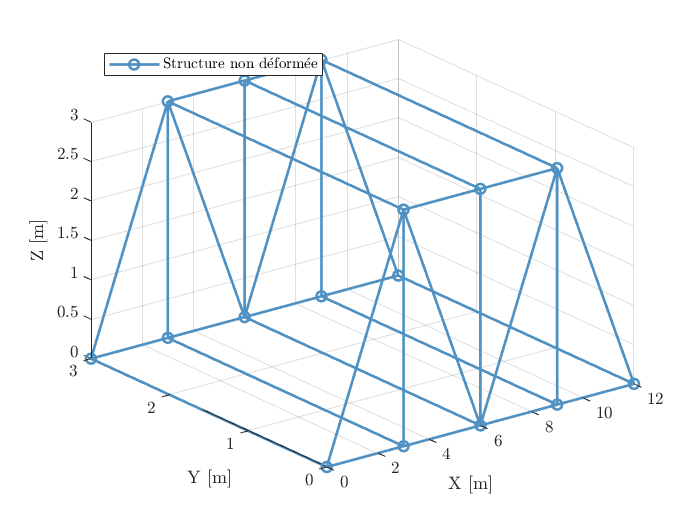

%representation of the bridge
if show == 1
    figure
    for i=1:length(elemList)
        plot3([nodeList(elemList(i,1),1) nodeList(elemList(i,2),1)],...
            [nodeList(elemList(i,1),2) nodeList(elemList(i,2),2)],...
            [nodeList(elemList(i,1),3) nodeList(elemList(i,2),3)],'-o','Color',myBlue);
        hold on
    end
    grid on
    axis([0 12 0 3 0 3]);
    xlabel('X [m]')
    ylabel('Y [m]')
    zlabel('Z [m]')
    legend('Structure non d\''eform\''ee','Location','northwest')
end

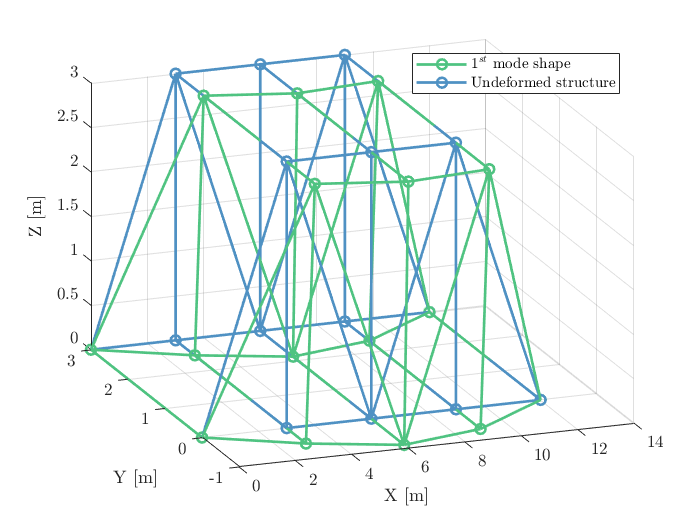

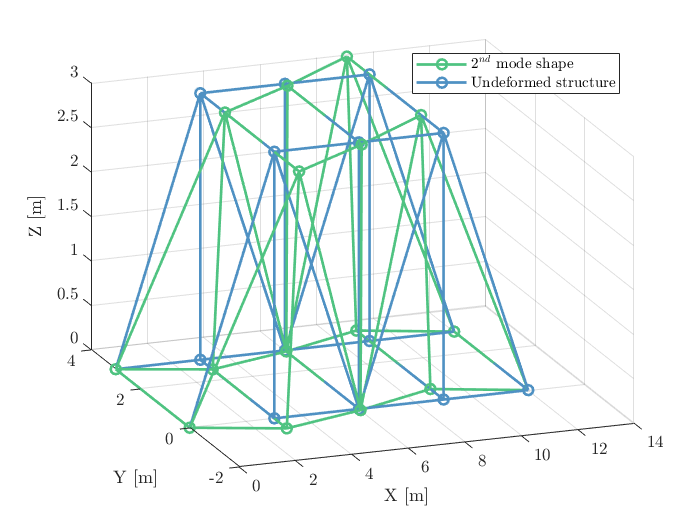

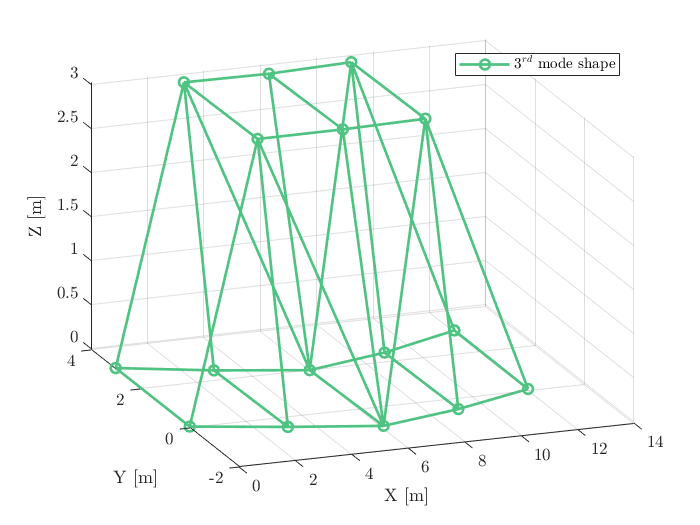

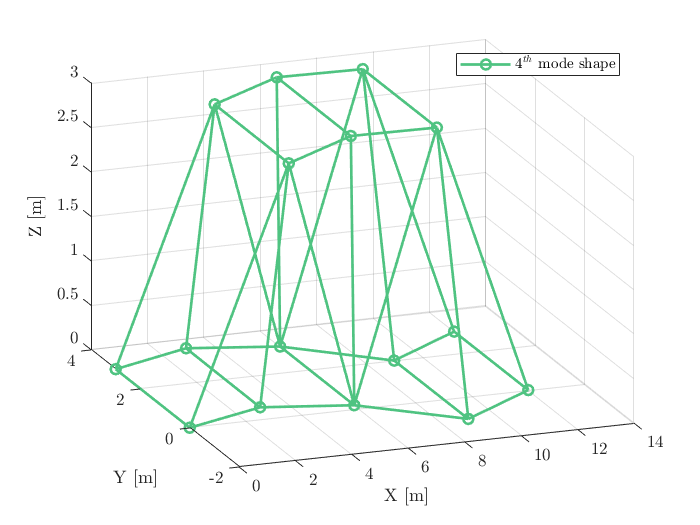

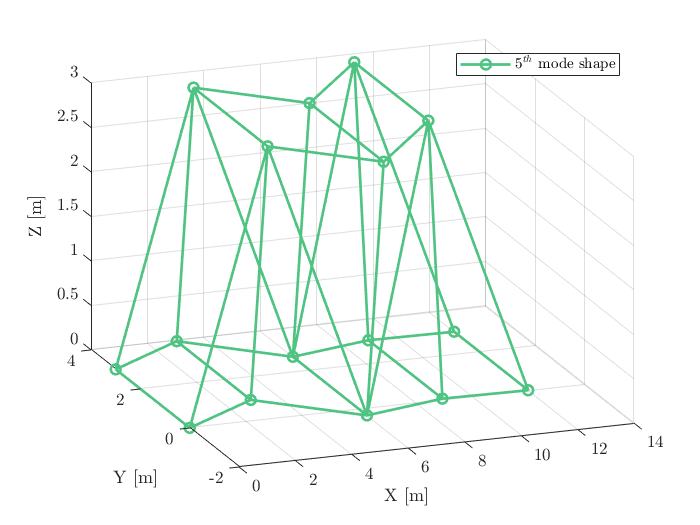

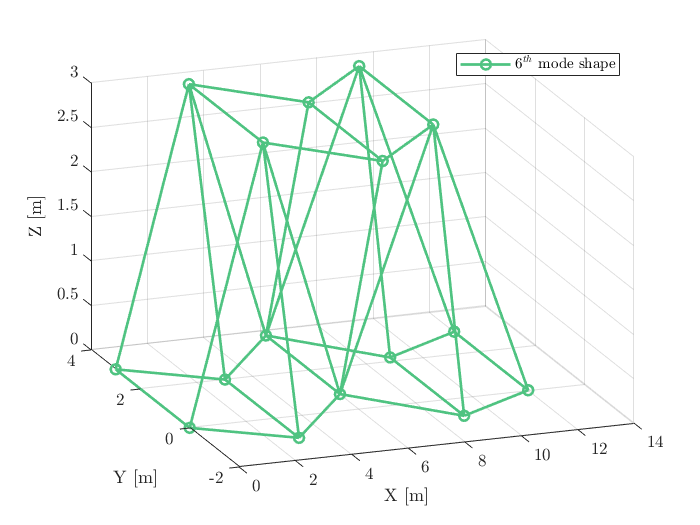

%Mode shapes 
deformedNodeList_1 = zeros(size(nodeList));
deformedNodeList_2 = zeros(size(nodeList));
deformedNodeList_3 = zeros(size(nodeList));
deformedNodeList_4 = zeros(size(nodeList));
deformedNodeList_5 = zeros(size(nodeList));
deformedNodeList_6 = zeros(size(nodeList));
for i=1:size(nodeList,1) % à chaque point, on ajoute les mode de translations (pas en rotation)
    deformedNodeList_1(i,1) = nodeList(i,1) + ModesNorm(6*i-5,1);
    deformedNodeList_1(i,2) = nodeList(i,2) + ModesNorm(6*i-4,1);
    deformedNodeList_1(i,3) = nodeList(i,3) + ModesNorm(6*i-3,1);
    deformedNodeList_2(i,1) = nodeList(i,1) + ModesNorm(6*i-5,2);
    deformedNodeList_2(i,2) = nodeList(i,2) + ModesNorm(6*i-4,2);
    deformedNodeList_2(i,3) = nodeList(i,3) + ModesNorm(6*i-3,2);
    deformedNodeList_3(i,1) = nodeList(i,1) + ModesNorm(6*i-5,3);
    deformedNodeList_3(i,2) = nodeList(i,2) + ModesNorm(6*i-4,3);
    deformedNodeList_3(i,3) = nodeList(i,3) + ModesNorm(6*i-3,3);
    deformedNodeList_4(i,1) = nodeList(i,1) + ModesNorm(6*i-5,4);
    deformedNodeList_4(i,2) = nodeList(i,2) + ModesNorm(6*i-4,4);
    deformedNodeList_4(i,3) = nodeList(i,3) + ModesNorm(6*i-3,4);
    deformedNodeList_5(i,1) = nodeList(i,1) + ModesNorm(6*i-5,5);
    deformedNodeList_5(i,2) = nodeList(i,2) + ModesNorm(6*i-4,5);
    deformedNodeList_5(i,3) = nodeList(i,3) + ModesNorm(6*i-3,5);
    deformedNodeList_6(i,1) = nodeList(i,1) + ModesNorm(6*i-5,6);
    deformedNodeList_6(i,2) = nodeList(i,2) + ModesNorm(6*i-4,6);
    deformedNodeList_6(i,3) = nodeList(i,3) + ModesNorm(6*i-3,6);
end
if show == 1 % affiche les graphes seulement si show vaut 1
    figure
    for i=1:length(elemList)
         plot3([nodeList(elemList(i,1),1) nodeList(elemList(i,2),1)],...
             [nodeList(elemList(i,1),2) nodeList(elemList(i,2),2)],...
             [nodeList(elemList(i,1),3) nodeList(elemList(i,2),3)],'-o','Color',myBlue);
        plot3([deformedNodeList_1(elemList(i,1),1) deformedNodeList_1(elemList(i,2),1)],...
            [deformedNodeList_1(elemList(i,1),2) deformedNodeList_1(elemList(i,2),2)],...
            [deformedNodeList_1(elemList(i,1),3) deformedNodeList_1(elemList(i,2),3)],'-o','Color',myGreen);
        hold on
    end
    xlabel('X [m]')
    ylabel('Y [m]')
    zlabel('Z [m]')
    legend('1$^{st}$ mode shape','Undeformed structure','Location','northeast')
    view([-45 -120 60])
    grid on
    figure
    for i=1:length(elemList)
        plot3([nodeList(elemList(i,1),1) nodeList(elemList(i,2),1)],...
             [nodeList(elemList(i,1),2) nodeList(elemList(i,2),2)],...
             [nodeList(elemList(i,1),3) nodeList(elemList(i,2),3)],'-o','Color',myBlue);
        plot3([deformedNodeList_2(elemList(i,1),1) deformedNodeList_2(elemList(i,2),1)],...
            [deformedNodeList_2(elemList(i,1),2) deformedNodeList_2(elemList(i,2),2)],...
            [deformedNodeList_2(elemList(i,1),3) deformedNodeList_2(elemList(i,2),3)],'-o','Color',myGreen);
        hold on
    end
    xlabel('X [m]')
    ylabel('Y [m]')
    zlabel('Z [m]')
    legend('2$^{nd}$ mode shape','Undeformed structure','Location','northeast')
    view([-45 -120 60])
    grid on
    figure
    for i=1:length(elemList)
        plot3([deformedNodeList_3(elemList(i,1),1) deformedNodeList_3(elemList(i,2),1)],...
            [deformedNodeList_3(elemList(i,1),2) deformedNodeList_3(elemList(i,2),2)],...
            [deformedNodeList_3(elemList(i,1),3) deformedNodeList_3(elemList(i,2),3)],'-o','Color',myGreen);
        hold on
    end
    xlabel('X [m]')
    ylabel('Y [m]')
    zlabel('Z [m]')
    grid on
    view([-45 -120 60])
    legend('3$^{rd}$ mode shape','Location','northeast')
    hgexport(gcf,'mode3_Matlab.eps')
    figure
    for i=1:length(elemList)
        plot3([deformedNodeList_4(elemList(i,1),1) deformedNodeList_4(elemList(i,2),1)],...
            [deformedNodeList_4(elemList(i,1),2) deformedNodeList_4(elemList(i,2),2)],...
            [deformedNodeList_4(elemList(i,1),3) deformedNodeList_4(elemList(i,2),3)],'-o','Color',myGreen);
        hold on
    end
    xlabel('X [m]')
    ylabel('Y [m]')
    zlabel('Z [m]')
    grid on
    view([-45 -120 60])
    legend('4$^{th}$ mode shape','Location','northeast')
    hgexport(gcf,'mode4_Matlab.eps')
    figure
    for i=1:length(elemList)
        plot3([deformedNodeList_5(elemList(i,1),1) deformedNodeList_5(elemList(i,2),1)],...
            [deformedNodeList_5(elemList(i,1),2) deformedNodeList_5(elemList(i,2),2)],...
            [deformedNodeList_5(elemList(i,1),3) deformedNodeList_5(elemList(i,2),3)],'-o','Color',myGreen);
        hold on
    end
    xlabel('X [m]')
    ylabel('Y [m]')
    zlabel('Z [m]')
    grid on
    view([-45 -120 60])
    legend('5$^{th}$ mode shape','Location','northeast')
    hgexport(gcf,'mode5_Matlab.eps')
    figure
    for i=1:length(elemList)
        plot3([deformedNodeList_6(elemList(i,1),1) deformedNodeList_6(elemList(i,2),1)],...
            [deformedNodeList_6(elemList(i,1),2) deformedNodeList_6(elemList(i,2),2)],...
            [deformedNodeList_6(elemList(i,1),3) deformedNodeList_6(elemList(i,2),3)],'-o','Color',myGreen);
        hold on
    end
    xlabel('X [m]')
    ylabel('Y [m]')
    zlabel('Z [m]')
    grid on
    view([-45 -120 60])
    legend('6$^{th}$ mode shape','Location','northeast')
    hgexport(gcf,'mode6_Matlab.eps')
end

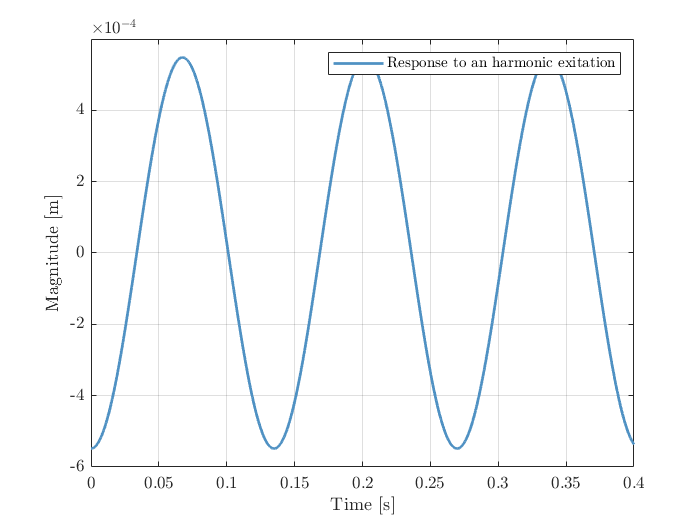

% Partie 2
amp = 500; %N
omega = 2*pi*445/60; %rad/s
s = zeros(nbNodes*6-16,1);
s(8)=amp;
x = (K-omega^2*M)^(-1)*s;
figure
Fs = 100000;
T=1/Fs;
t = 0:T:30-T;
L=length(t);
q=x(8)*cos(omega*t);
plot(t,q,'Color',myBlue);
axis([0 0.4 -6e-4 6e-4])
xlabel('Time [s]')
ylabel('Magnitude [m]')
grid on
legend('Response to an harmonic exitation','Location','northeast')

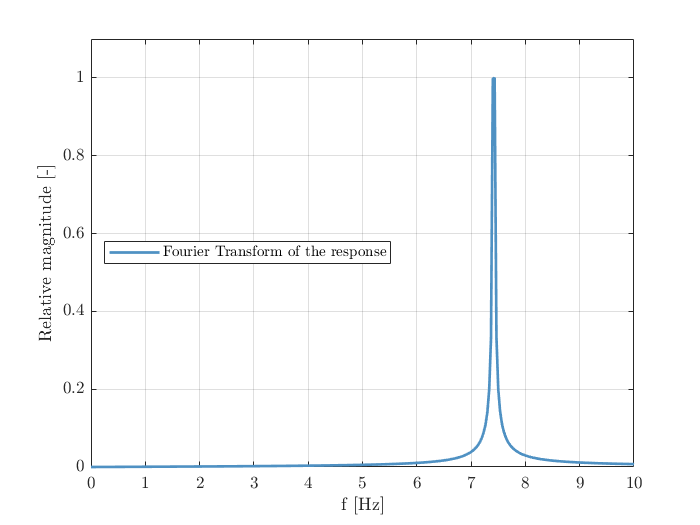

figure
FFT = fft(q);
P2 = abs(FFT/L);
P1 = P2(1:L/2+1);
P1(2:end-1)=2*P1(2:end-1);
f = Fs*(0:L/2)/L;
plot(f,P1/max(P1),'Color',myBlue);
axis([0 10 0 1.1]);
xlabel('f [Hz]')
ylabel('Relative magnitude [-]')
grid on
legend('Fourier Transform of the response','Location','west')

freqRes = f(find(P1==max(P1)));
fprintf('Le pic de fréquence se trouve en %d \n',freqRes);

Le pic de fréquence se trouve en 7.433333e+00 


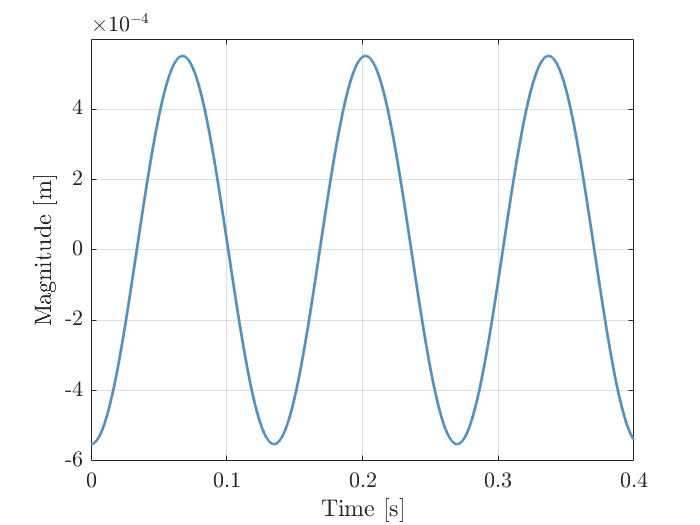

k=6;
w2=(sortedFrequencies*2*pi).^2;
sum_d=0;
sum_a=0;
for i = 1:k
    mu = sortedModes(:,i).'*M*sortedModes(:,i);
    xx = sortedModes(:,i)*sortedModes(:,i).';
    xx_d = xx/((w2(i)-omega^2)*mu);
    xx_a = xx/((w2(i)-omega^2)*w2(i)*mu);
    sum_d= sum_d + xx_d;
    sum_a= sum_a + xx_a;
end
xxx_d = sum_d*s;
xxx_a = (sum_a*omega^2+K^(-1))*s;
qqq_d = xxx_d(8)*cos(omega*t);
qqq_a = xxx_a(8)*cos(omega*t);
figure
plot(t,qqq_d,'Color',myBlue);
axis([0 0.4 -6e-4 6e-4]);
grid on
xlabel('Time [s]');
ylabel('Magnitude [m]');

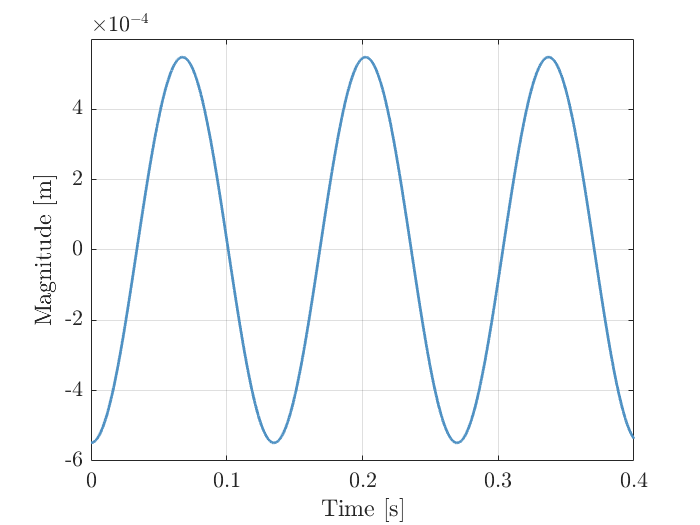

figure
plot(t,qqq_a,'Color',myBlue);
axis([0 0.4 -6e-4 6e-4]);
grid on
xlabel('Time [s]');
ylabel('Magnitude [m]');